# ASEN 2004

Tristan Workman, ID: 109326637, last modified 

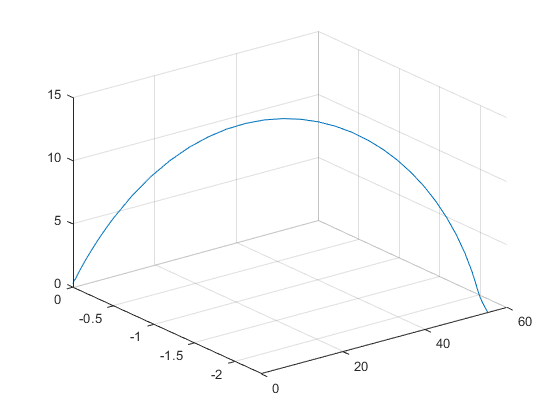

endpoint =    55.3456   -2.3339


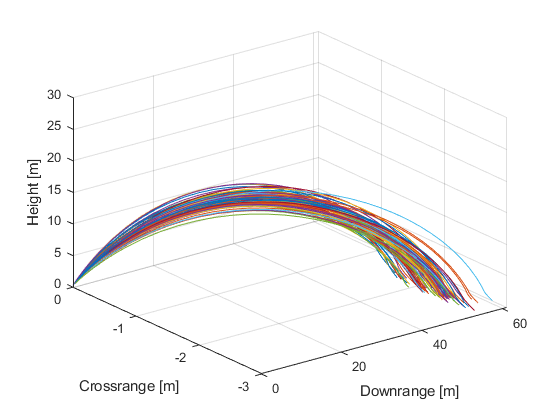

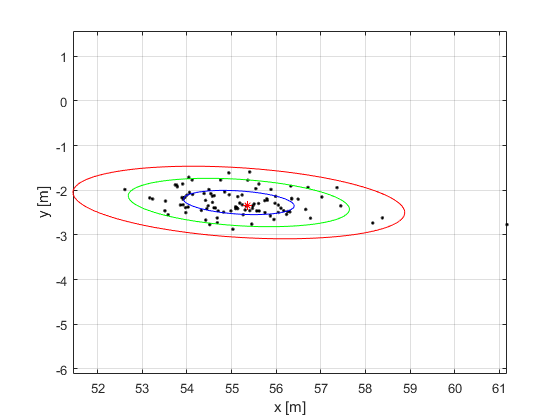

% Using thermodynamic and aerodynamic relations, and equations of motion, determine 
% the trajectory of a bottle rocket with specified initial properties

% wind (+/- 11.25 degrees from SW), (+/- .1 m/s wind speed)
% mass (+/- .5 gram), launchpad angle (+/- 1 degree)
% bottle diameter (+/- .1 cm), bottle throat (+/- .1 cm)
% pressure (+/- 3447.38 Pa)

% Assumptions
% Steady, uniform 1D flow, only 2D required, Ideal weather + Gas,
% Compressible within the bottle (two densities)

g = 9.81; % [m/s^2]
C_discharge = 0.8; % discharge coefficient
rho_amb = 0.961; % kg/m^3 ambient air density
Vol_bottle = 0.002; % m^3 volume of empty bottle
P_amb = 83426.56; % Pa atmospheric pressure
gamma = 1.4; % ratio of specific heats for air
rho_water = 1000; % kg/m^3 density of water
R = 287; % J/kgK gas constant of air
M_bottle = 0.128; % kg mass of empty 2 litre bottle with cones and fins
T_airI = 289.817; % K initial temperature of air
v0 = 0.0; % m/s initial velocity of rocket
x0 = 0.0; % m initial horizontal displacement
y0 = 0.0; % m initial lateral displacement
z0 = 0.25; % m initial vertical displacement
l_s = 0.5; % m length of test stand
tspan = [0 5]; % integration time
windspeed = 1.34112; % m/s
windangle = deg2rad(45); % radians

% After meeting the verification requirements, I begin to try test cases
% make 1 true and all others false to see associated graph 
% Verification case on by default
verification = true;

if (verification == true)
    P_gage = 275790; % initial gage pressure of air in bottle
    Vol_waterI = 1.001/rho_water; % m^3 initial volume of water inside bottle
    C_drag = 0.38; % drag coefficient
    theta = deg2rad(45); % radians initial angle of rocket
    
    D_throat = 2.1; % cm diameter of the throat
    D_bottle = 10.5; % cm diameter of bottle
    
    A_t = pi * (D_throat/200)^2; % m^2 area of throat
    A_B = pi * (D_bottle/200)^2; % m^2 cross sectional area of bottle
    
    % determining rocket mass
    P_airI = (P_gage + P_amb);
    rho_air_bottleI = P_airI ./ (R .* T_airI);
    M_waterI = (Vol_waterI .* rho_water); 
    Vol_airI = (Vol_bottle - Vol_waterI);
    M_airI = (P_airI .* Vol_airI)./(R .* T_airI);
    RMI = M_bottle + M_waterI + M_airI;
    
    X0 = [x0,y0,z0,v0,v0,v0,RMI,M_airI,Vol_airI];
    
    opt = odeset('Events', @stopEvent);
    [t, X] = ode45(@(t,x) odeFun(t,x,g,C_discharge,rho_amb,Vol_bottle,P_amb,gamma,rho_water,A_t,R,C_drag,T_airI,theta,l_s,Vol_airI,P_airI,M_airI,A_B,x0,z0,y0,windspeed,windangle), tspan, X0, opt);
    figure
    plot3(X(:,1),X(:,2),X(:,3))
    grid on
    hold off
    endpoint = [X(end,1),X(end,2)]
    simulationM(100, endpoint)
end

## Function propogation

function [value, isterminal, direction] = stopEvent(t,X)
    value = (X(3) <= 0);
    isterminal = 1;
    direction = 0;
end
function dx = odeFun(t,x,g,C_discharge,rho_amb,Vol_bottle,P_amb,gamma,rho_water,A_t,R,C_drag,T_airI,theta,l_s,Vol_airI,P_airI,M_airI,A_B,x0,z0,y0,windspeed,windangle)
    % must split into three parts, as there are three sections of flight
    % Part 1 is powered (water exhaust), so drag + thrust(water) + gravity
    % Part 2 is also powered (air exhaust), so drag + thrust(air) + gravity
    % Part 3 is unpowered, so just drag + gravity
    xpos = x(1);
    ypos = x(2);
    zpos = x(3);
    Vx = x(4);
    Vy = x(5);
    Vz = x(6);
    RM = x(7);
    AM = x(8);
    AV = x(9);
    
    % Part 1
    if (AV < Vol_bottle) 
        % calculating change in volume of air over time
        AVdot = C_discharge .* A_t .* sqrt((2./rho_water) .* ((P_airI .* (Vol_airI./AV).^gamma) - P_amb));
        % calculating current pressure based on volume
        P_air = P_airI .* (Vol_airI./AV).^gamma;
        % calculating change in mass of the rocket over time
        RMdot = -C_discharge .* A_t .* sqrt(2 .* rho_water .* (P_air - P_amb));
        % with P_air we can now calculate the force from thrust
        F_t = 2 .* C_discharge .* A_t .* (P_air - P_amb);
        % change in air mass is zero because of phase of flight
        AMdot = 0;
    else
        % set pressure and temperature to fixed values after all water is
        % expelled (AV >= Vol_bottle) && (P_air > P_amb)
        % calculating pressure at end of part 1
        P_air_end = P_airI .* (Vol_airI./Vol_bottle).^gamma;
        % calculating temperature at the end of part 1
        T_air_end = T_airI .* (Vol_airI./Vol_bottle).^(gamma-1);
        % Air pressure now changes (no water left in the bottle)
        % calculating new pressure
        P_air = P_air_end .* (AM./M_airI).^gamma;
    end
    
    % Part 2
    if (AV >= Vol_bottle) && (P_air > P_amb)
        % Calculating air density/temperature
        rho_air_bottle = AM./Vol_bottle;
        T_air = P_air ./ (rho_air_bottle .* R);
        % determining whether choked flow, need critical pressure
        P_crit = P_air .* (2 ./ (gamma + 1)).^(gamma./(gamma-1));
        if (P_crit > P_amb)
            % flow is choked, determine exit velocity
            % need temperature at exit
            T_exit = T_air .* (2./(gamma+1));
            % calculating exit velocity
            V_exit = sqrt(gamma .* R .* T_exit);
            % air pressure at exit is just critical pressure
            P_exit = P_crit;
            % calculating air density at exit
            rho_air_exit = P_exit ./ (R .* T_exit);
        elseif (P_crit < P_amb)
            % solve for exit mach speed through pressure relation
            Mach_exit = sqrt((((P_air./P_amb).^((gamma-1)./gamma))-1)./((gamma-1)./2));
            % calculating temperature of air at exit
            T_exit = T_air ./ (1 + (((gamma-1)./2) .* (Mach_exit.^2)));
            % air pressure at exit is just ambient pressure
            P_exit = P_amb;
            % calculating density at exit
            rho_air_exit = P_exit ./ (R .* T_exit);
            % now we can calculate exit velocity
            V_exit = Mach_exit .* sqrt(gamma .* R .* T_exit);
        end
        % thrust, air mass, and rocket mass change by the same functions
        % calculating change in air mass
        AMdot = -C_drag .* rho_air_exit .* A_t .* V_exit;
        % calculating thrust
        F_t = (-AMdot) .* V_exit + ((P_amb - P_exit) .* A_t);
        % Calculating change in rocket mass (same as change in air mass)
        RMdot = AMdot;
        % Air volume is unchanging during this phase
        AVdot = 0;
    end
    
    % Part 3
    if (AV >= Vol_bottle) && (P_air <= P_amb)
        % no water or air exhaust thrust
        F_t = 0;
        AVdot = 0;
        % Change in air mass is zero, as pressure has equalized
        AMdot = 0;
        % change in mass is zero (again no exhaust and pressure equalized)
        RMdot = 0;
    end
    
%     if (zpos < 5)
%         
%     elseif (zpos <= 22 && zpos > 3)
%         
%         windx = (zpos/22 * windspeed) * sin(abs(deg2rad(40) - windangle));
%         windy = (zpos/22 * windspeed) * cos(abs(deg2rad(40) - windangle));
%         
%         Vx = Vx - windx;
%         Vy = Vy - windy;
%         
%         hx = (Vx)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
%         hz = (Vz)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
%         hy = (Vy)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
%     else
%         
%     end
    
    % initial heading is determined by test stand
    % so we have to check whether its cleared the stand yet (using trig)
    % if (sqrt(((zpos - z0)^2) + ((xpos - x0)^2)) <= l_s)
    if (xpos < (l_s .* cos(theta) + x0) && zpos < (l_s .* sin(theta) + z0) && t < 2)
        % once it has cleared the stand, heading is determined by velocity
        % components
        hx = cos(theta);
        hz = sin(theta);
        hy = 0;
    elseif (zpos <= 22 && zpos >= (l_s .* sin(theta) + z0))
        windx = (zpos./22)*windspeed * sin(abs(deg2rad(40) - windangle));
        windy = (zpos./22)*windspeed * cos(abs(deg2rad(40) - windangle));
        
        Vx = Vx - windx;
        Vy = Vy - windy;
        hx = (Vx)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
        hz = (Vz)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
        hy = (Vy)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
    else
        windx = windspeed * sin(abs(deg2rad(40) - windangle));
        windy = windspeed * cos(abs(deg2rad(40) - windangle));
        
        Vx = Vx - windx;
        Vy = Vy - windy;
        hx = (Vx)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
        hz = (Vz)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
        hy = (Vy)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
    end
    
    % velocity vector is just combination of components
    V = sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
    
    % Since drag force is a simple function of area and velocity, it can
    % be calculated outside of the individual parts
    
    % Calculating drag:
    F_d = (1/2) .* rho_amb .* V^2 .* C_drag .* A_B;
    
    
    % Now, we have all forces responsible for motion 
    % We can now determine the acceleration components which govern
    % trajectory:
    accelX = ((F_t .* hx) - (F_d .* hx)) ./ RM; 
    accelZ = ((F_t .* hz) - (F_d .* hz) - (RM .* g)) ./ RM;
    accelY = ((F_t .* hy) - (F_d .* hy)) ./ RM;
    
    % final outputs for state vector
    dx = [Vx; Vy; Vz; accelX; accelY; accelZ; RMdot; AMdot; AVdot];
end
function [] = simulationM(N, endpoint)
    % constants
    g = 9.81; % [m/s^2]
    C_discharge = 0.8; % discharge coefficient
    rho_amb = 0.961; % kg/m^3 ambient air density
    Vol_bottle = 0.002; % m^3 volume of empty bottle
    P_amb = 83426.56; % Pa atmospheric pressure
    gamma = 1.4; % ratio of specific heats for air
    rho_water = 1000; % kg/m^3 density of water
    R = 287; % J/kgK gas constant of air
    M_bottle = 0.128; % kg mass of empty 2 litre bottle with cones and fins
    T_airI = 289.817; % K initial temperature of air
    v0 = 0.0; % m/s initial velocity of rocket
    x0 = 0.0; % m initial horizontal displacement
    y0 = 0.0; % m initial lateral displacement
    z0 = 0.25; % m initial vertical displacement
    l_s = 0.5; % m length of test stand
    tspan = [0 5]; % integration time
    
    % mass
    mp = 1.001 + 0.005*randn(N,1);
    ms = M_bottle + 0.005*randn(N,1);
    
    % bottle geometry
    D_throat = 2.1 + 0.1 * randn(N,1); % cm diameter of the throat
    D_bottle = 10.5 + 0.1 * randn(N,1); % cm diameter of bottle
    A_t = pi .* (D_throat./200).^2; % m^2 area of throat
    A_B = pi .* (D_bottle./200).^2; % m^2 cross sectional area of bottle
    
    % environment (wind)
    windspeed = 1.34112 + 0.1*randn(N,1); % m/s
    windangle = deg2rad(45 + 11.25*randn(N,1)); % radians
    
    P_gage = 275790 + (3447 * randn(N,1)); % initial gage pressure of air in bottle
    Vol_waterI = mp./rho_water; % m^3 initial volume of water inside bottle
    C_drag = 0.38; % drag coefficient
    theta = deg2rad(45 + randn(N,1)); % radians initial angle of rocket
    
    % determining rocket mass
    P_airI = (P_gage + P_amb);
    rho_air_bottleI = P_airI ./ (R .* T_airI);
    M_waterI = (Vol_waterI .* rho_water); 
    Vol_airI = (Vol_bottle - Vol_waterI);
    M_airI = (P_airI .* Vol_airI)./(R .* T_airI);
    RMI = ms + M_waterI + M_airI;
    
   
    
    opt = odeset('Events', @stopEvent);
    
    % vectors to fill with final landing values
    Lx = zeros();
    Ly = zeros();
    figure
    for i = 1:N 
        X0 = [x0,y0,z0,v0,v0,v0,RMI(i),M_airI(i),Vol_airI(i)];
        [t, X] = ode45(@(t,x) odeFun(t,x,g,C_discharge,rho_amb,Vol_bottle,P_amb,gamma,rho_water,A_t(i),R,C_drag,T_airI,theta(i),l_s,Vol_airI(i),P_airI(i),M_airI(i),A_B(i),x0,z0,y0,windspeed(i),windangle(i)), tspan, X0, opt);
        plot3(X(:,1),X(:,2),X(:,3))
        hold on
        xlabel('Downrange [m]')
        ylabel('Crossrange [m]')
        zlabel('Height [m]')
        zlim([0 30]);
        grid on;
        
        Lx(i) = X(end,1);
        Ly(i) = X(end,2);
    end
    hold off
    
    % plotting error ellipses
    figure; plot(Lx,Ly,'k.','markersize',6)
    axis equal; grid on; xlabel('x [m]'); ylabel('y [m]'); hold on;
    plot(endpoint(1),endpoint(2),'r*','markersize',6)
    
    % Calculate covariance matrix
    P = cov(Lx,Ly);
    mean_x = mean(Lx);
    mean_y = mean(Ly);
     
    % Calculate the define the error ellipses
    n=100; % Number of points around ellipse
    p=0:pi/n:2*pi; % angles around a circle
     
    [eigvec,eigval] = eig(P); % Compute eigen-stuff
    xy_vect = [cos(p'),sin(p')] * sqrt(eigval) * eigvec'; % Transformation
    x_vect = xy_vect(:,1);
    y_vect = xy_vect(:,2);
     
    % Plot the error ellipses overlaid on the same figure
    plot(1*x_vect+mean_x, 1*y_vect+mean_y, 'b')
    plot(2*x_vect+mean_x, 2*y_vect+mean_y, 'g')
    plot(3*x_vect+mean_x, 3*y_vect+mean_y, 'r')
    hold off
end